clc; clear;

## LQR Controller for redezvous of two spacecraft regularization

Author: Andres Pulido December 2021

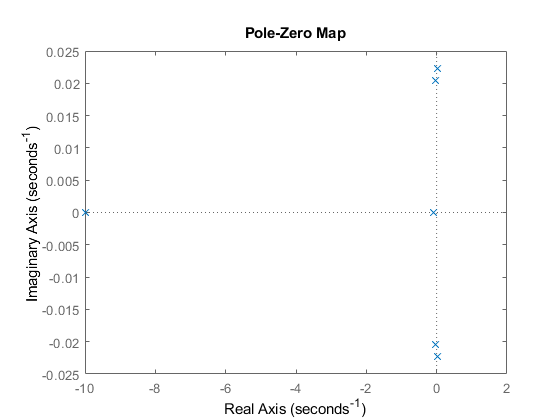

n = 9.1017e-4;
m = 1.66e-3;
A = [0 0 1 0;0 0 0 1;3*n^2 n 0 2*n;-n 0 -2*n 0];
B = [0 0;0 0;m 0;0 m];
%C = [1 0 0 0;0 0 0 0;0 0 0 0;0 0 0 1;0 0 0 0;0 0 0 0];
%C = [1 0 0 0;0 0 0 0;0 0 0 0;0 0 0 1];
C = eye(4);
%D = [0 0;0 0;0 0;0 0;1 0;0 1];
D = [0 0;0 0;0 0;0 0];

P = ss(A, B, C, D);

X_0 = [-3.1; -39.16; 0.00002; 0.0041; 0; 0];

Actuator1 = tf(1,[0.1, 1]);
Actuator2 = tf(1,[10, 1]);
Actuators = append(Actuator1, Actuator2);
PA = series(Actuators, P);
pzmap(PA)

## PID Regulation

% PID1 = pid(80.7,1.05,1377.5,255.15);
% PID2 = pid(0.41,12.13,57.35,7.52);
% PID = append(PID1, PID2);
% p = [];
% T = feedback(PA, PID, [1 2], [1 2]);
% 
% 
% t = 0:.001:200;
% [y, t, ~] = initial(T,[X_0',0,0,0,0],t);
% plot([t,t,t],y(:,[1,3,4]))
% plot(t,y(:,2))

## LQR Regulation

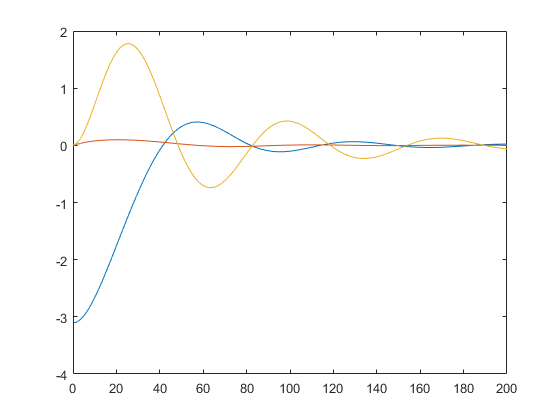

Q = diag([1, 1, 1, 1]);
R = 0.1;
K = lqr(A,B,Q,R);
T = feedback(PA,K,[1 2],[1 2 3 4]);

t = 0:.001:200;
[y, t, x] = initial(T,X_0,t);
plot([t,t,t],x(:,[1,3,4]))

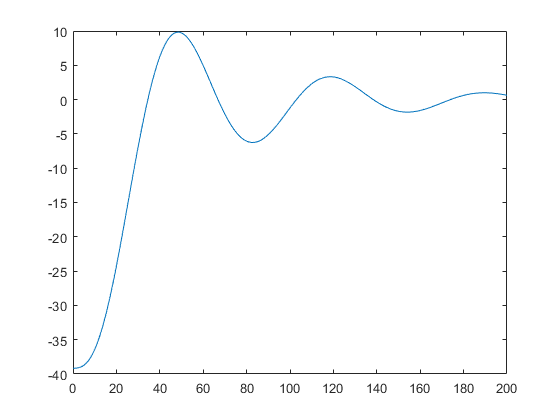

plot(t,y(:,2))

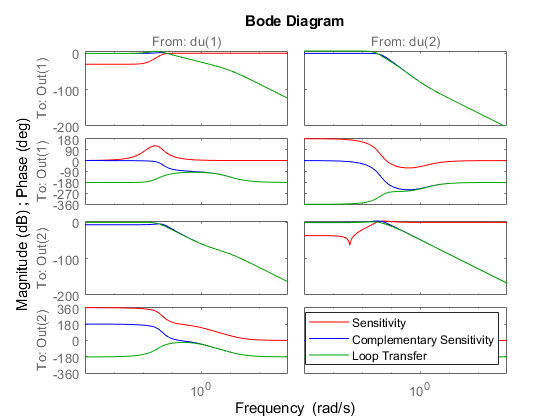




Q1 = diag([1, 0.001, 1, 0.01]);
Q2 = diag([1, 0.0001, 1, 1]);
Q3 = diag([1, 0.01, 1, 0.01]);
Q4 = diag([1, 0.1, 1, 1]);
R = 1;
 
K = lqr(A,B,Q,R);
K1 = lqr(A,B,Q1,R);
K2 = lqr(A,B,Q2,R);
K3 = lqr(A,B,Q3,R);
K4 = lqr(A,B,Q4,R);

loops = loopsens(PA, K3);
bode(loops.Si,'r',loops.Ti,'b',loops.Li,'g')
legend('Sensitivity','Complementary Sensitivity','Loop Transfer')


T = feedback(PA,K,[1 2],[1 2 3 4], -1);
T1 = feedback(PA,K1,[1 2],[1 2 3 4], -1);
T2 = feedback(PA,K2,[1 2],[1 2 3 4], -1);
T3 = feedback(PA,K3,[1 2],[1 2 3 4], -1);
T4 = feedback(PA,K4,[1 2],[1 2 3 4], -1);

y1 = initial(T1,X_0,t);
y2 = initial(T2,X_0,t);
y3 = initial(T3,X_0,t);
y4 = initial(T4,X_0,t);
y = initial(T,X_0,t);

plot(t,y(:,1),'k',t,y1(:,1),'r',t,y2(:,1),'g', t, y3(:,1),'y', t, y4(:,1),'b');
plot(t,y(:,2),'k',t,y1(:,2),'r',t,y2(:,2),'g', t, y3(:,2),'y', t, y4(:,2),'b');
plot(t,y(:,3),'k',t,y1(:,3),'r',t,y2(:,3),'g', t, y3(:,3),'y', t, y4(:,3),'b');
plot(t,y(:,4),'k',t,y1(:,4),'r',t,y2(:,4),'g', t, y3(:,4),'y', t, y4(:,4),'b');


## Make closed-loop with observer

% My guess for the dynamics (purposely make them wrong)
%
Aguess = A;       % my guess for state matrix is correct
Bguess = B;          % my guess for input matrix is correct
Cguess = [1 0 0 0;0 1 0 0;0 0 1 0;0 0 0 1];      % We can only measure x position and y_dot position
Dguess = zeros(4,2);          % my guess for feedthrough matrix is correct

%
% Try Q,R matrices for dual problem
%
Qdual = diag([1, 10, 10, 1]);
Rdual = 0.001;

%
% Make observer gain as controller for dual system
%
L = lqr(Aguess',Cguess',Qdual,Rdual);   % compute controller
L = L';                                 % take transpose from dual system
%
% Make observer to have full-state output
%
Aobserver = Aguess - L*Cguess;
Bobserver = [Bguess L];
Cobserver = eye(4);
Dobserver = zeros(4,6);
O = ss(Aobserver,Bobserver,Cobserver,Dobserver);

%
% Augment previous LQR controller to get states from observer
%
KK = series(O,K1);

%
% Make closed-loop system
%
YU = append(PA, K1);
%TO = feedback(YU,KK, , [1 2 3 4 5 6]);
G = series(I,-K3(3));
S = series(G,T);
X = feedback(S,1,1,1);

%
% Compute step response
%
%X_0_o = [X_0',0 0]

t = 0:.1:10;
[yy,tt] = step(X,t);

%
% Plot the response using full-state feedback (we called them y3 made K3) 
%   against the response using observer-estimated states
%
figure(5)
plot(t,y3(:,1),'k',t,yy(:,1),'r');
legend('measured states','observer states');
ylabel('Position');

figure(6)
plot(t,y3(:,2),'k',t,yy(:,2),'r');
legend('measured states','observer states');
ylabel('Velocity');


figure(7)
plot(t,y3(:,3),'k',t,yy(:,3),'r');
legend('measured states','observer states');
ylabel('Actuation');